# 神经网络近似求解微分方程

clc, clear, rng(0)

`考虑一阶常微分方程`


$$\frac{\mathrm{d}y_{t}(x;\mathbf{p})}{\mathrm{d}x}=f\left(x,y_{t}(x;\mathbf{p})\right)$$


尝试使用$N(x;\mathbf{p})$`为1-n-1前馈神经网络近似求解该常微分方差，其具有如下形式：`


$$N(x;\mathbf{p})=\sum_{j=1}^{n}v_{j}\varphi(z_{j}),\quad z_{j}=w_{j}x-\theta_{j}$$


`其中，`$\mathbf{p}=\left(\mathbf{w},\mathbf{v},\mathbf{\theta}\right)^{\prime}$`，`$w_{j}$`是从输入节点`$x$`到隐藏层第`$j$`个节点的权重，`$v_{j}$`是隐藏层第`$j$`个节点到输出节点的权重，`$\theta_{j}$`是隐藏层第`$j$`个节点的阈值，`$\varphi(z)=\frac{1}{1+\mathrm{e}^{-z}}$`为Sigmoid型激活函数。`

N = @ (x, w, v, theta) sum(v' ./ (1 + exp(theta' - x * w')), 2);

`假设该常微分方程的实验解`$y_{t}(x)$`具有如下形式`


$$y_{t}(x;\mathbf{p})=y_0+xN(x;\mathbf{p})$$


yt= @ (x, y0, w, v, theta) y0 + x .* N(x, w, v, theta);

`我们希望对于实验解`$y_{t}(x)$在对应`区间`$[0,1]$内`，它能够尽可能地满足常微分方程，因此，将`$x$`在区间`$[0,1]$`离散化，取`$0=x_{1},x_{2},\ldots,x_{m}=1$，得到如下优化问题


$$\min_{\mathbf{p}}\,\sum_{i=1}^{m}\left[\left.\frac{\mathrm{d}y_{t}(x;\mathbf{p})}{\mathrm{d}x}\right|_{x=x_{i}}-f\left(x_{i},y_{t}(x_{i};\mathbf{p})\right)\right]^{2}$$


`考虑以下常微分方程问题：`


$$\frac{\mathrm{d}y(x)}{\mathrm{d}x}=f(x,y)=x-y+1,\quad y(0)=1$$


`使用1-n-1前馈神经网络`$N(x;\mathbf{p})$`在`$x\in[0,1]$`范围内，求解其实验解`$y_{t}(x)$。

f = @(x, y) x -y + 1;
df_dy = @(x, y) - ones(length(y), 1);

`其精确解为`


$$y(x)=x+\mathrm{e}^{-x}$$


y = @(x) x + exp(-x);

`前述问题最终可转换为如下优化问题`


$$\min_{\mathbf{p}}\sum_{i=1}^{m}\left\{-x_{i}+\left[\sum_{j=1}^{n}\left(1+x_{i}\right)\frac{v_{j}}{1+\mathrm{e}^{\theta_{j}-w_{j}x_{i}}}+x_{i}\frac{v_{j}w_{j}\mathrm{e}^{\theta_{j}-w_{j}x_{i}}}{\left(1+\mathrm{e}^{\theta_{j}-w_{j}x_{i}}\right)^{2}}\right]\right\}^{2}$$


`其中，`$\mathbf{p}=\left(\mathbf{w},\mathbf{v},\mathbf{\theta}\right)^{\prime}$`为该1-n-1前馈神经网络的参数。`考虑`在不同网络节点数 （`$n=2,3,4$`）和训练元素个数（`$m=3,5,10$`）的情况下`

n = 3;
m = 4;

`为方便起见，令`$x_{i}$`取`$[0,1]$`上均匀分布的点，`

x = linspace(0, 1, m)'; y0 = 1;

给定初始值$\mathbf{p}$服从正态分布，使用 BFGS 方法对该问题进行求解：

p0 = randn(3 * n, 1);
objFcn = @(p) loss_1ode(p, x, f, df_dy, y0);
options = optimoptions('fminunc', "Algorithm", "quasi-newton",...
    'HessUpdate', 'bfgs', 'SpecifyObjectiveGradient', true);
[p, loss] = fminunc(objFcn, p0, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


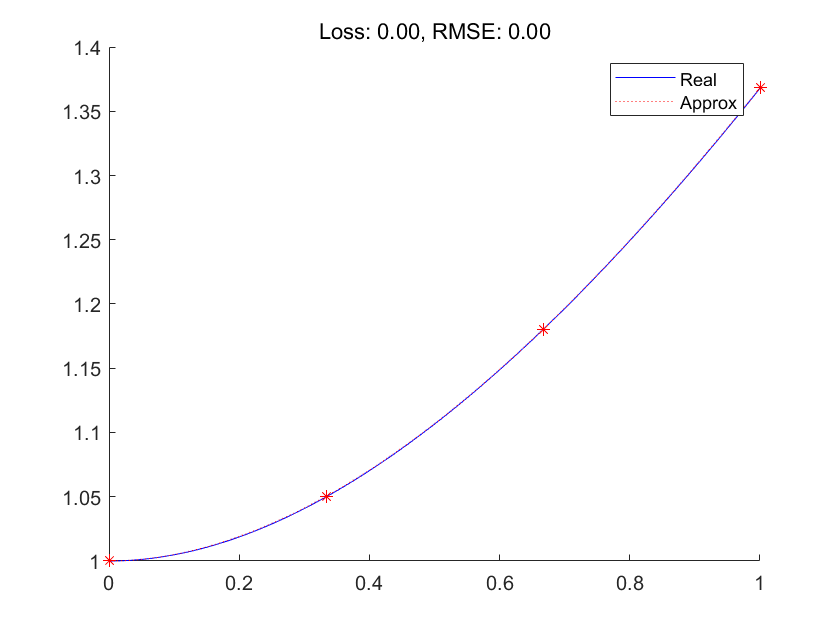

w = p(1:n);
v = p(n+1:2*n);
theta = p(2*n+1:3*n);

x_pred = linspace(0, 1, 1000)';
y_true = y(x_pred);

y_pred = yt(x_pred, y0, w, v, theta);
y_train = yt(x, y0, w, v, theta);
rmse = sqrt(mean((y_true - y_pred) .^ 2));
clf, hold on
plot(x_pred, y_true, "b-")
plot(x, y_train, "r*")
plot(x_pred, y_pred, "r:")
legend({'Real', '', 'Approx'})
title(sprintf('Loss: %.2f, RMSE: %.2f', [loss, rmse]))
hold off

考虑另一常微分问题，


$$\frac{\mathrm{d}y(x)}{\mathrm{d}x}=f(x,y)=x^{3}-\frac{y}{x},\quad y(0)=\frac{2}{5}$$


f = @(x, y) x .^ 3 - y ./ x;
df_dy = @(x, y) - 1 ./  x;

其精确解为


$$y(x)=\frac{x^{4}}{5}+\frac{1}{5x}$$


y = @(x) x .^ 4 / 5 + 1 ./ (5 * x);

考虑`在不同网络节点数 （`$n=2,3,4$`）和训练元素个数（`$m=3,5,10$`）的情况下`

n = 2;
m = 6;

`为方便起见，令`$x_{i}$`取`$[1,2]$`上均匀分布的点，`

x = linspace(1, 2, m)'; y0 = 0.4;

给定初始值$\mathbf{p}$服从正态分布，使用 BFGS 方法对该问题进行求解：

p0 = randn(3 * n, 1);
objFcn = @(p) loss_1ode(p, x, f, df_dy, y0);
options = optimoptions('fminunc', "Algorithm", "quasi-newton",...
    'HessUpdate', 'bfgs', 'SpecifyObjectiveGradient', true);
[p, loss] = fminunc(objFcn, p0, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


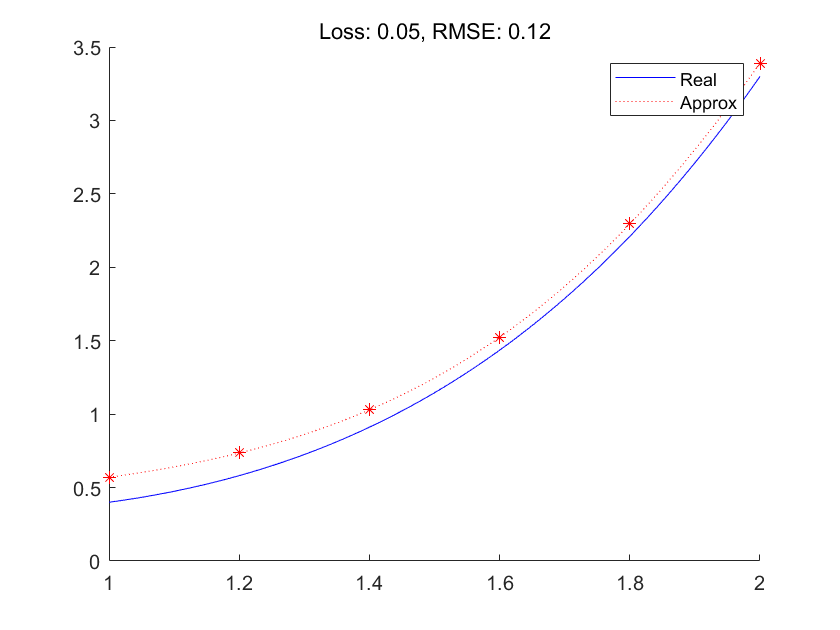

w = p(1:n);
v = p(n+1:2*n);
theta = p(2*n+1:3*n);

x_pred = linspace(1, 2, 1000)';
y_true = y(x_pred);

y_pred = yt(x_pred, y0, w, v, theta);
y_train = yt(x, y0, w, v, theta);
rmse = sqrt(mean((y_true - y_pred) .^ 2));
clf, hold on
plot(x_pred, y_true, "b-")
plot(x, y_train, "r*")
plot(x_pred, y_pred, "r:")
legend({'Real', '', 'Approx'})
title(sprintf('Loss: %.2f, RMSE: %.2f', [loss, rmse]))
hold off